clear all;
% --------------------------------------------------------------
% Parameters
% --------------------------------------------------------------
a1 = 1.2272 %[cm2] Area of outlet pipe 1

a1 = 1.2272

a2 = 1.2272 %[cm2] Area of outlet pipe 2

a2 = 1.2272

a3 = 1.2272 %[cm2] Area of outlet pipe 3

a3 = 1.2272

a4 = 1.2272 %[cm2] Area of outlet pipe 4

a4 = 1.2272

A1 = 380.1327 %[cm2] Cross sectional area of tank 1

A1 = 380.1327

A2 = 380.1327 %[cm2] Cross sectional area of tank 2

A2 = 380.1327

A3 = 380.1327 %[cm2] Cross sectional area of tank 3

A3 = 380.1327

A4 = 380.1327 %[cm2] Cross sectional area of tank 4

A4 = 380.1327

gamma1 = 0.45; % Flow distribution constant. Valve 1
gamma2 = 0.40; % Flow distribution constant. Valve 2
g = 981; %[cm/s2] The acceleration of gravity
rho = 1.00; %[g/cm3] Density of water
p = [a1; a2; a3; a4; A1; A2; A3; A4; gamma1; gamma2; g; rho];
% --------------------------------------------------------------
t0 = 0.0; % [s] Initial time
tf = 20*60; % [s] Final time
Ts = 10; % [s] Sample Time
t = [t0:Ts:tf]'; % [s] Sample instants
N = length(t);
m10 = 0; % [g] Liquid mass in tank 1 at time t0
m20 = 0; % [g] Liquid mass in tank 2 at time t0
m30 = 0; % [g] Liquid mass in tank 3 at time t0
m40 = 0; % [g] Liquid mass in tank 4 at time t0
F1 = 300; % [cm3/s] Flow rate from pump 1
F2 = 300; % [cm3/s] Flow rate from pump 2
x0 = [m10; m20; m30; m40];
u = [repmat(F1,1,N); repmat(F2,1,N)];
% Process Noise
Q = [20^2 0;0 40^2];
Lq = chol(Q,'lower');
w = Lq*randn(2,N);
% Measurement Noise
R = eye(4);
Lr = chol(R,'lower');
v = Lr*randn(4,N);
% --------------------------------------------------------------

nx = 4; nu = 2; ny = 4; nz = 2;
x = zeros(nx,N);
y = zeros(ny,N);
z = zeros(nz,N);
X = zeros(0,nx);
T = zeros(0,1);
x(:,1) = x0;
for k = 1:N-1
y(:,k) = FourTankSystemSensor(x(:,k),p)+v(:,k); % Sensor function
z(:,k) = FourTankSystemOutput(x(:,k),p); % Output function
[Tk,Xk] = ode15s(@FourTankSystem,[t(k) t(k+1)],x(:,k),[],...
u(:,k)+w(:,k),p);
x(:,k+1) = Xk(end,:)';
T = [T; Tk];
X = [X; Xk];
end
k = N;
y(:,k) = FourTankSystemSensor(x(:,k),p)+v(:,k); % Sensor function
z(:,k) = FourTankSystemOutput(x(:,k),p); % Output function

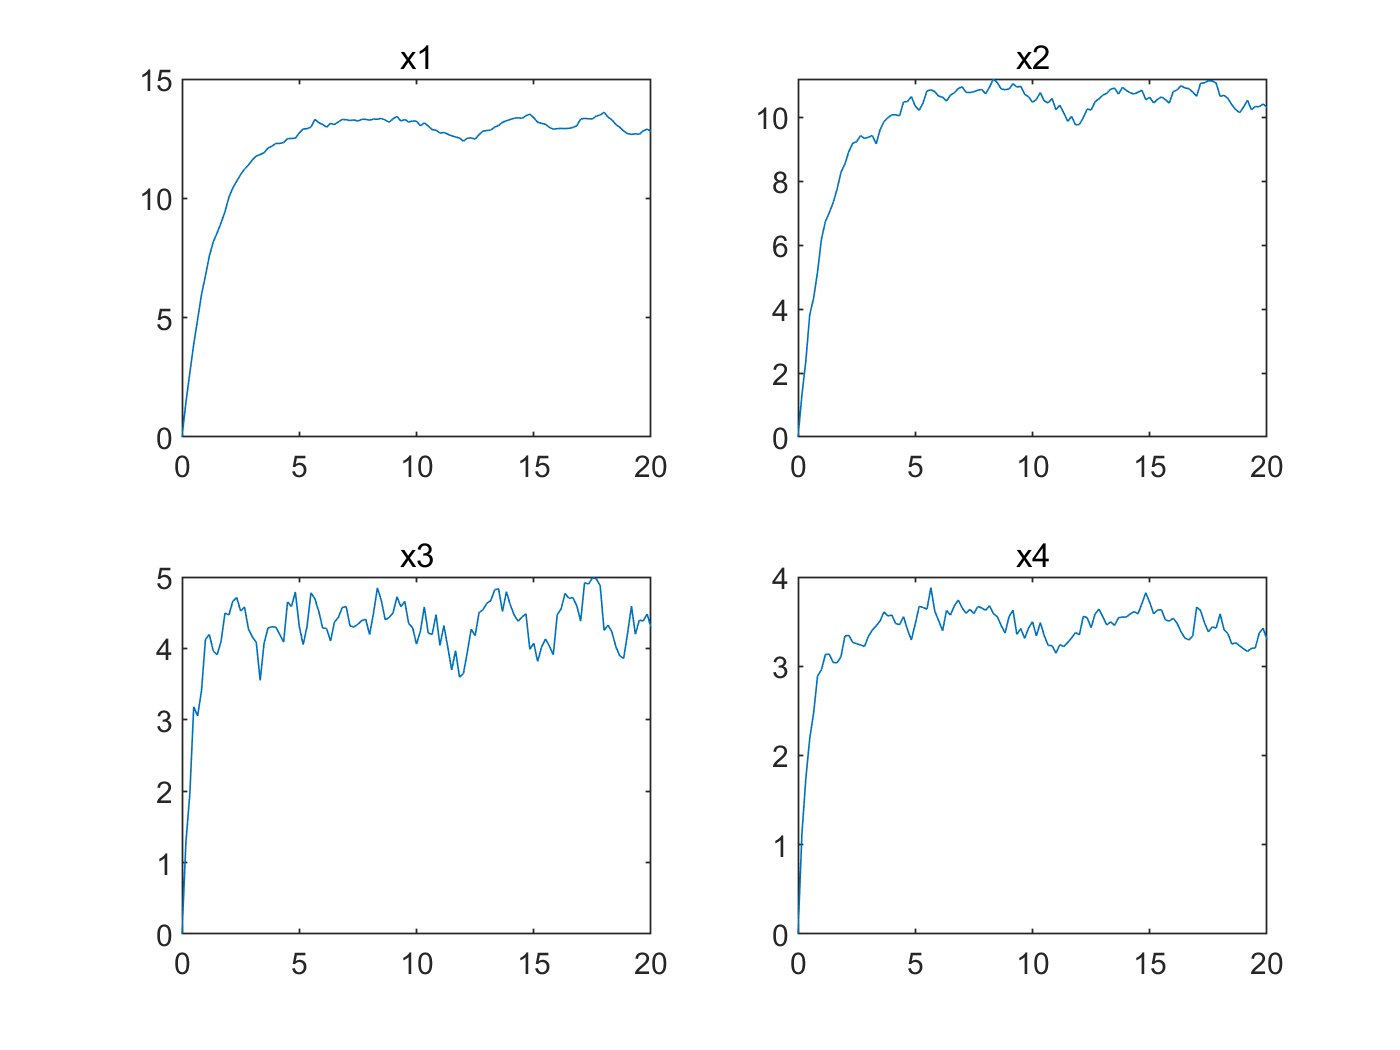

%plot x 
figure
subplot(2,2,1)
plot(t/60,x(1,:)/1e3)
title('x1')
subplot(2,2,2)
plot(t/60,x(2,:)/1e3)
title('x2')
subplot(2,2,3)
plot(t/60,x(3,:)/1e3)
title('x3')
subplot(2,2,4)
plot(t/60,x(4,:)/1e3)
title('x4')

%steady state control
xs0 = 5000*ones(4,1); % Initial guess of steady state
us = [300; 300]; % Steady-state inputs
xs = fsolve(@FourTankSystemWrap,xs0,[],us,p)%也就是一个系统中在某一组状态周围对应于某一组input,状态会回到原点（这组状态）,也可以理解为input也是稳态，线性化后加入更微小的变量


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


xs = 	1.0e+04 *

    1.2765
    1.0449
    0.4168
    0.3502


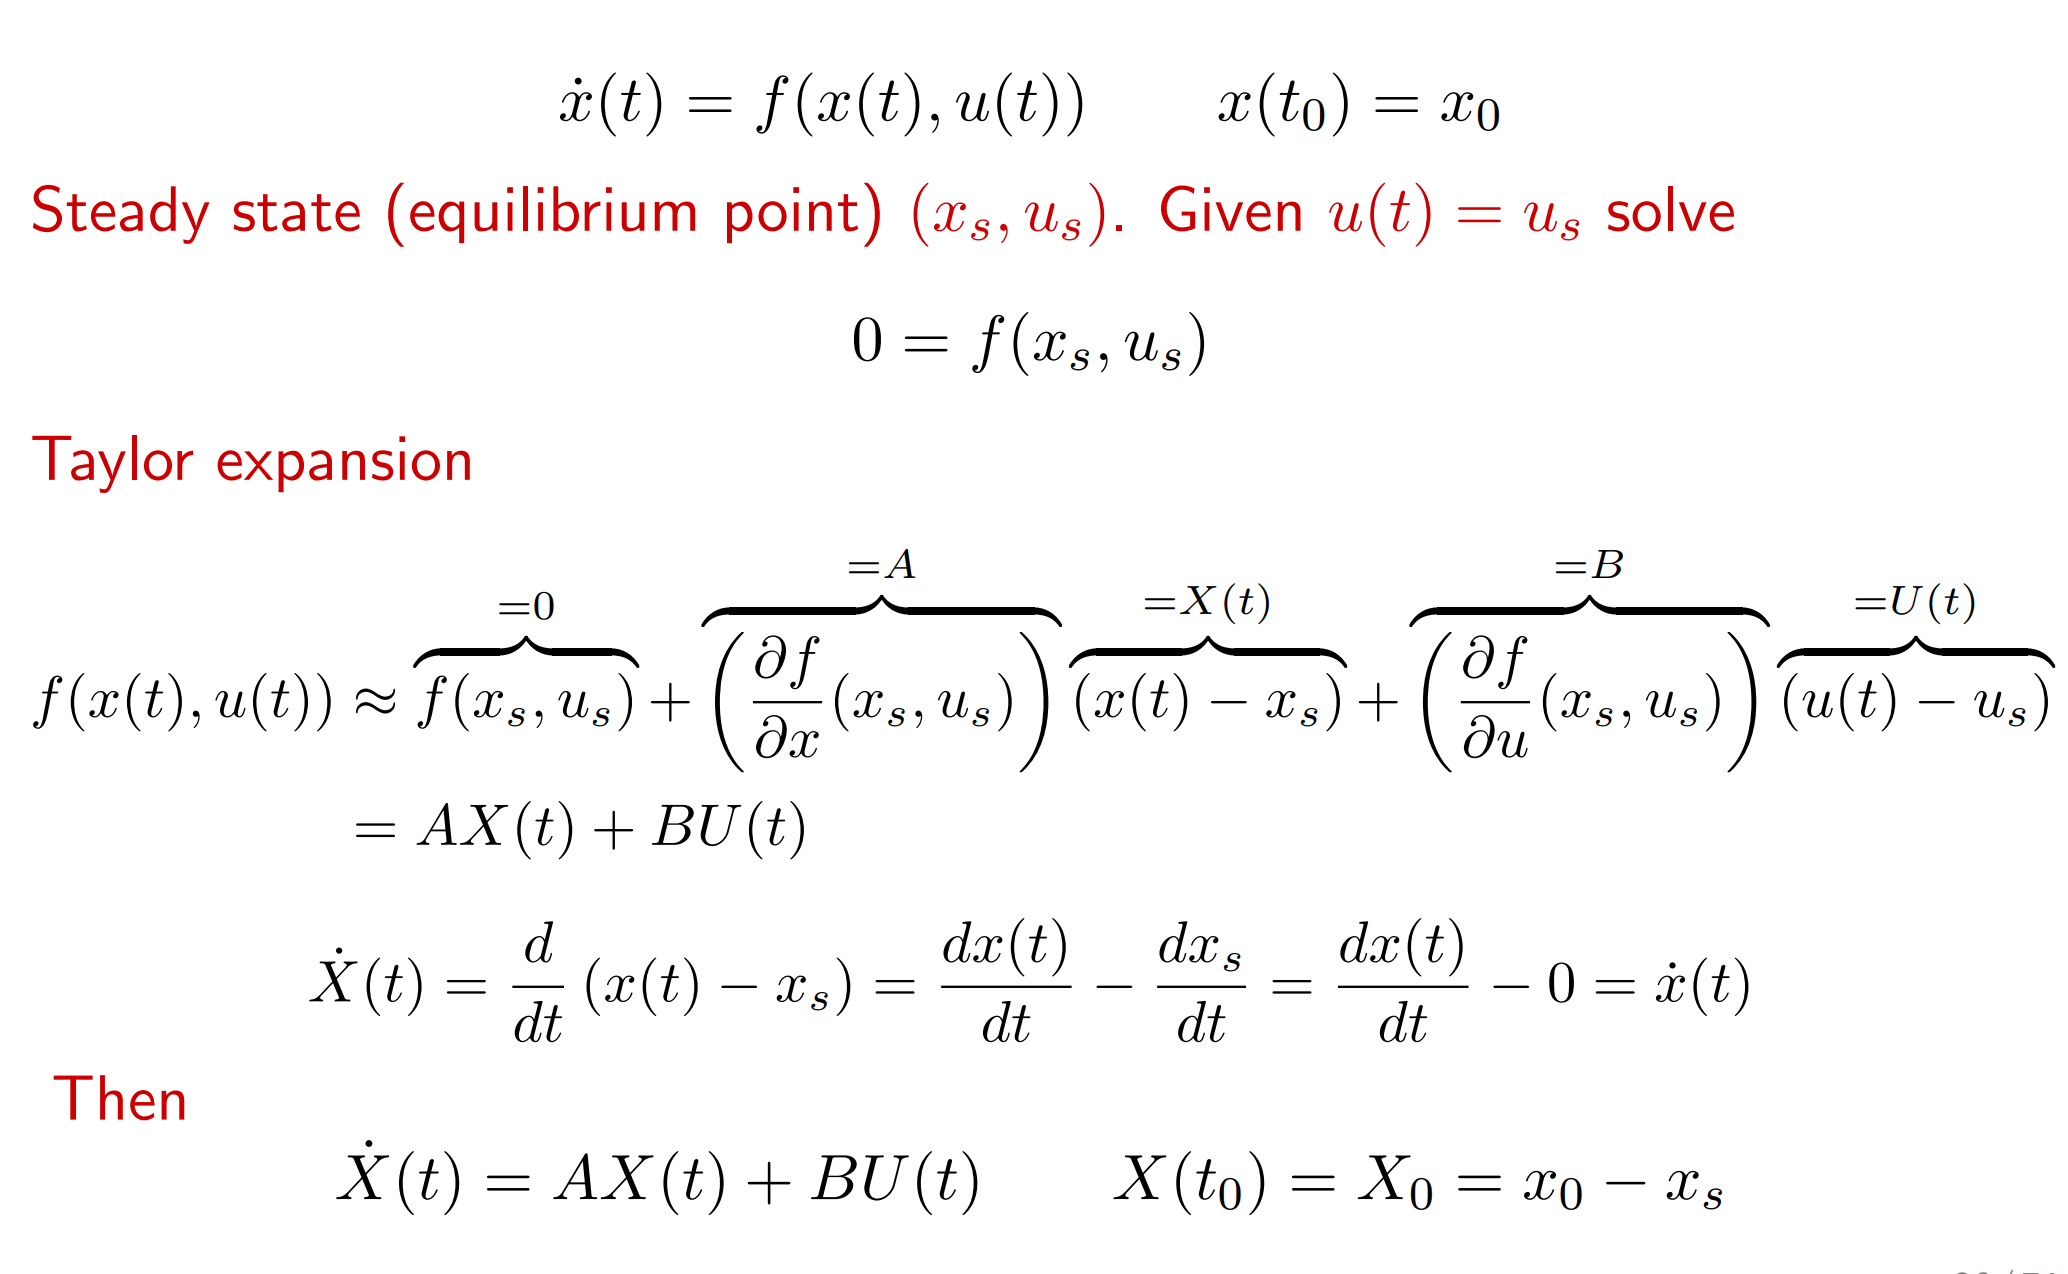

%下面进行非线性系统的在平稳点的线性化
% --------------------------------------------------------------
% Parameters
% --------------------------------------------------------------
ap = [a1; a2; a3; a4]; % [cm2] Pipe cross sectional areas
At = [A1; A2; A3; A4]; % [cm2] Tank cross sectional areas
gam = [gamma1; gamma2]; % [-] Valve constants
g = 981; %[cm/s2] The acceleration of gravity
rho = 1.00; %[g/cm3] Density of water
p = [ap; At; gam; g; rho];
% --------------------------------------------------------------
% Steady State
% --------------------------------------------------------------
us = [300; 300] % [cm3/s] Flow rates

us =    300
   300


xs0 = [5000; 5000; 5000; 5000] % [g] Initial guess on xs

xs0 =         5000
        5000
        5000
        5000


xs = fsolve(@FourTankSystemWrap,xs0,[],us,p)


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


xs = 	1.0e+04 *

    1.2765
    1.0449
    0.4168
    0.3502


ys = FourTankSystemSensor(xs,p)

ys =    33.5808
   27.4891
   10.9652
    9.2138


zs = FourTankSystemOutput(xs,p)

zs =    33.5808
   27.4891


% --------------------------------------------------------------
% Linearization
% --------------------------------------------------------------
hs = ys;
T = (At./ap).*sqrt(2*hs/g)

T =    81.0487
   73.3298
   46.3135
   42.4541


A=[-1/T(1) 0 1/T(3) 0;0 -1/T(2) 0 1/T(4);0 0 -1/T(3) 0;0 0 0 -1/T(4)]

A =    -0.0123         0    0.0216         0
         0   -0.0136         0    0.0236
         0         0   -0.0216         0
         0         0         0   -0.0236


B=[rho*gam(1) 0;0 rho*gam(2); 0 rho*(1-gam(2)); rho*(1-gam(1)) 0]

B =     0.4500         0
         0    0.4000
         0    0.6000
    0.5500         0


C=diag(1./(rho*At))

C =     0.0026         0         0         0
         0    0.0026         0         0
         0         0    0.0026         0
         0         0         0    0.0026


Cz=C(1:2,:)

Cz =     0.0026         0         0         0
         0    0.0026         0         0


## 关于时域的状态空间方程的拉普拉斯变换后与传递函数之间很好的一个推导

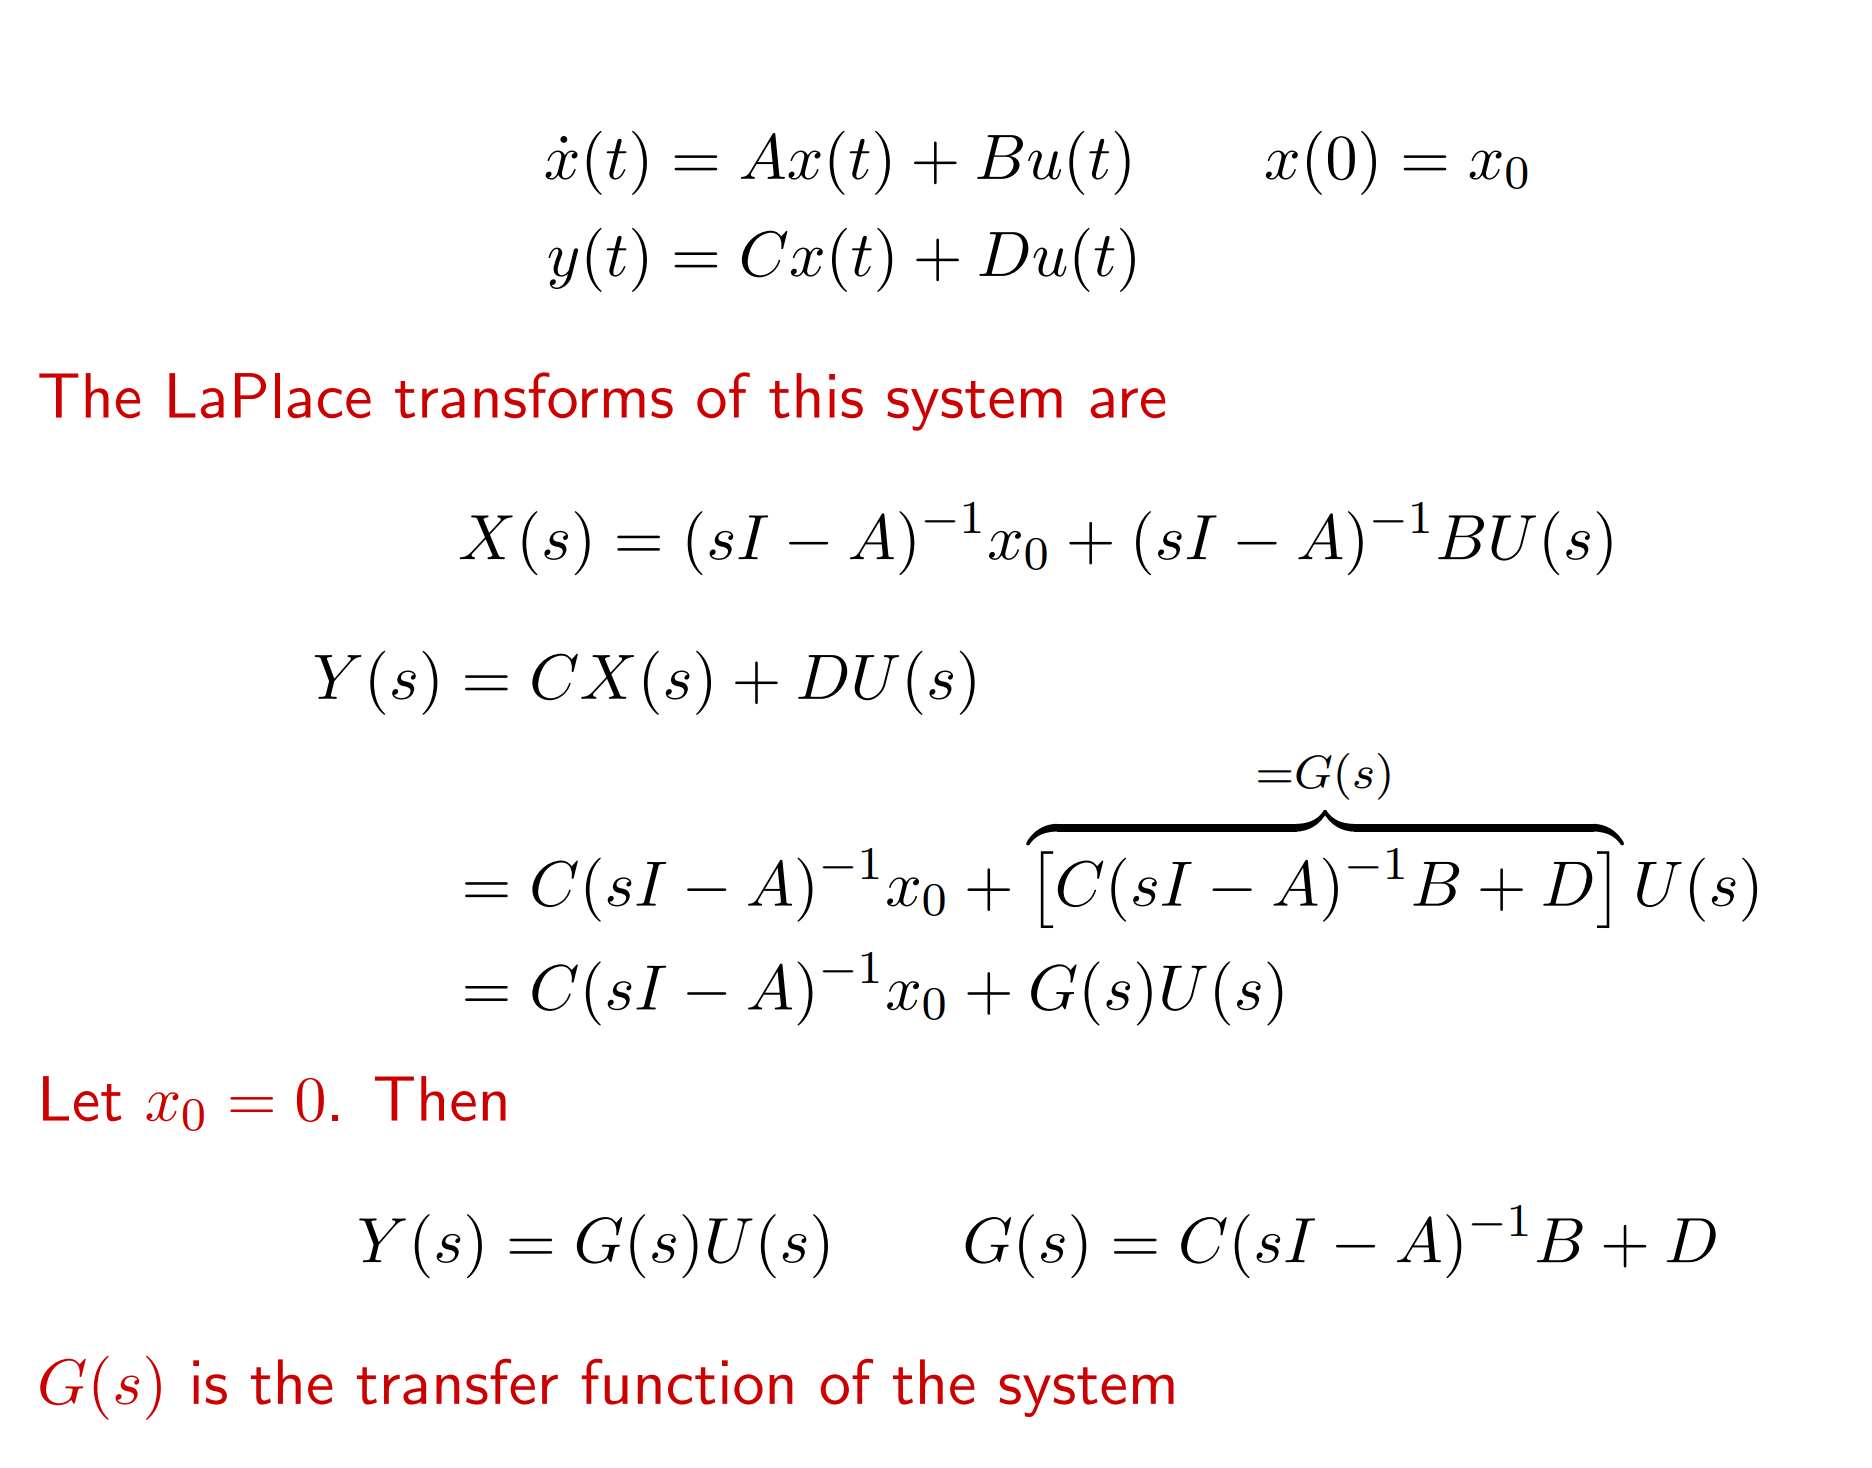

## 古典控制的传递函数，标准化对分析很有用

# 这里是关于零极点表示的形式

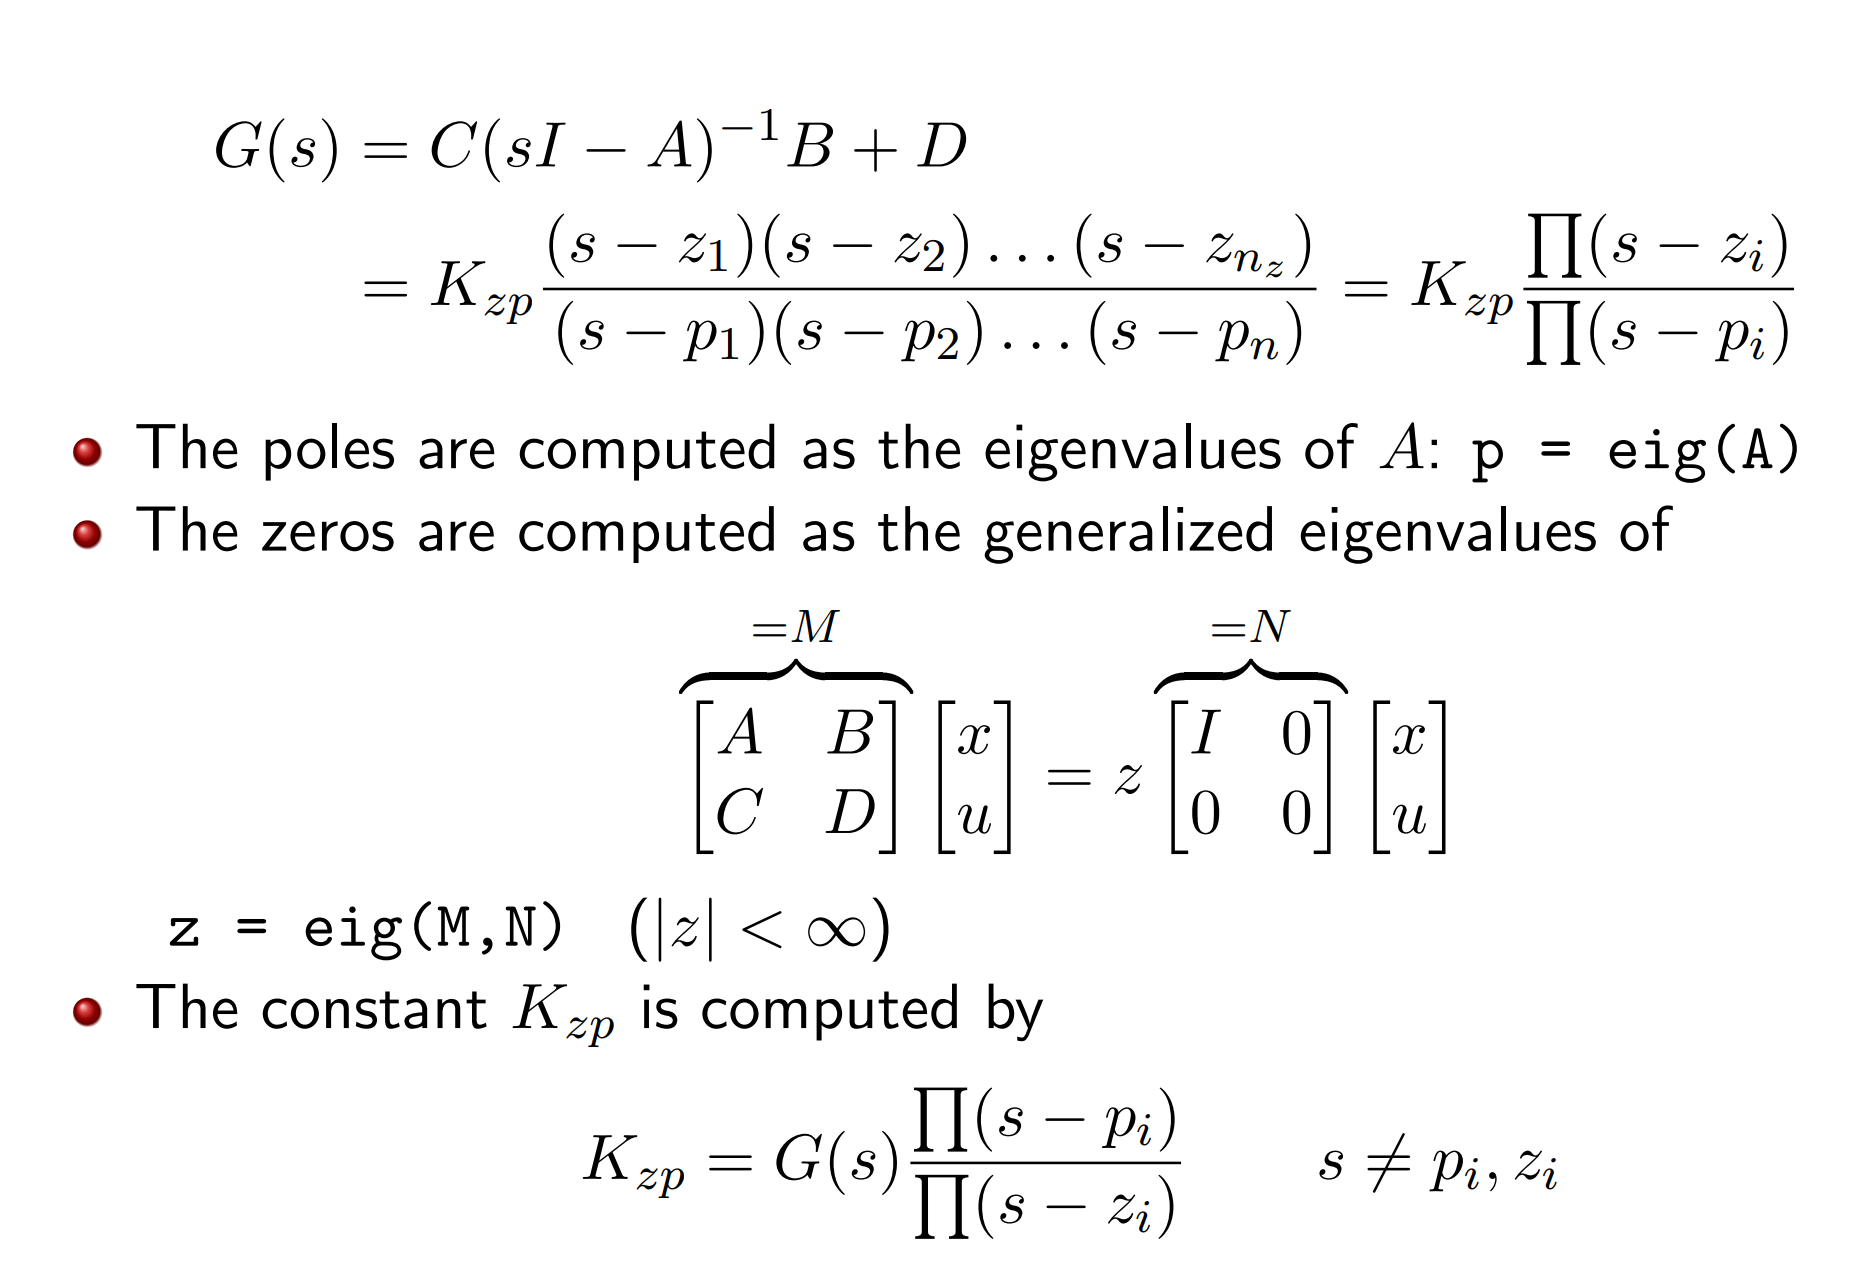

# 一个example，下面的标准型对于判断由几个子传递函数构成很有帮助

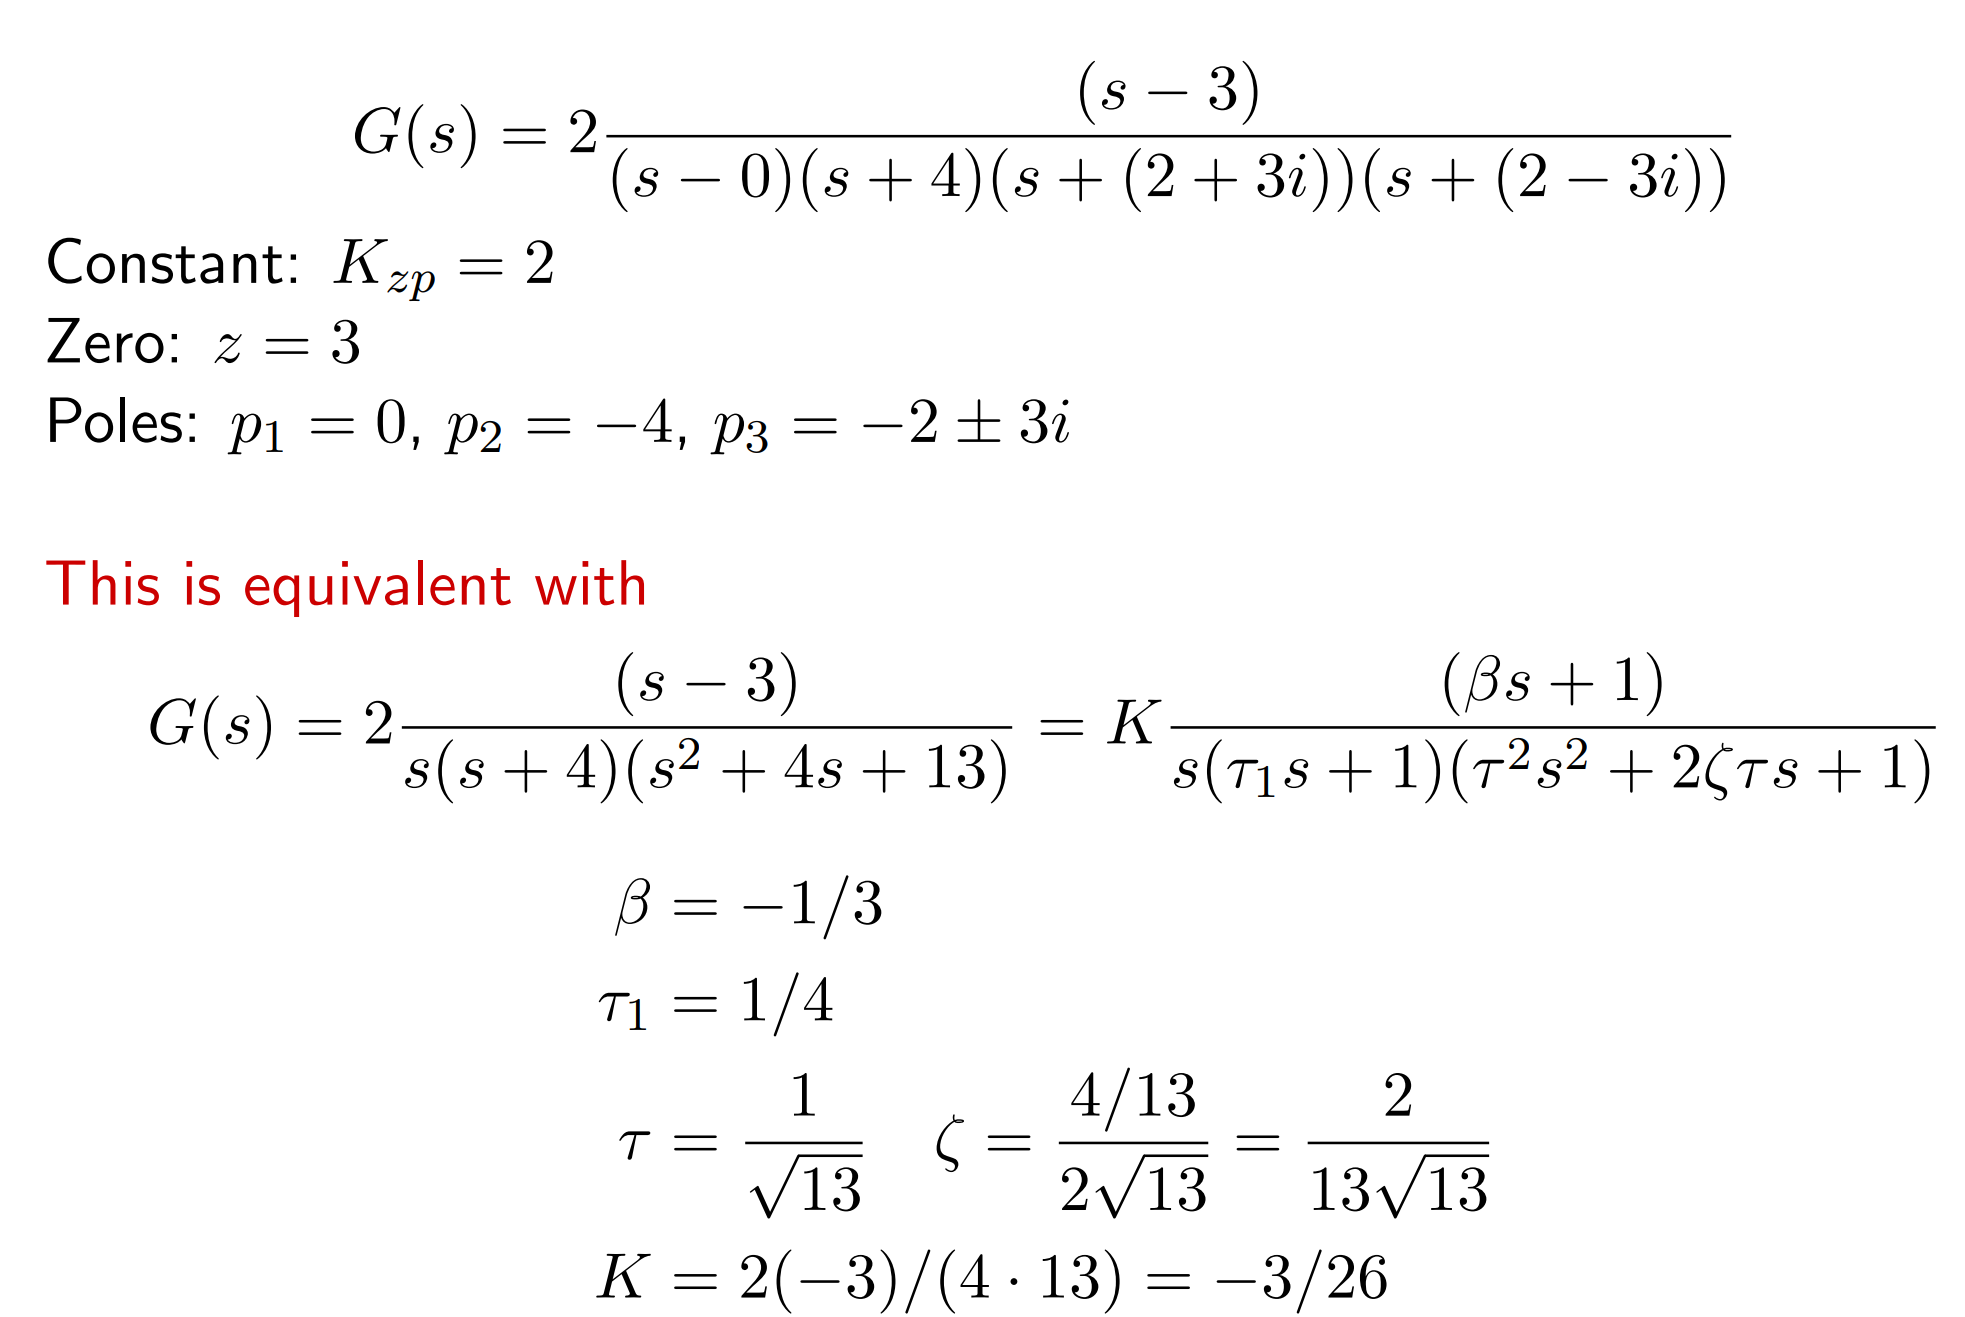

# 下面是常用的传递函数

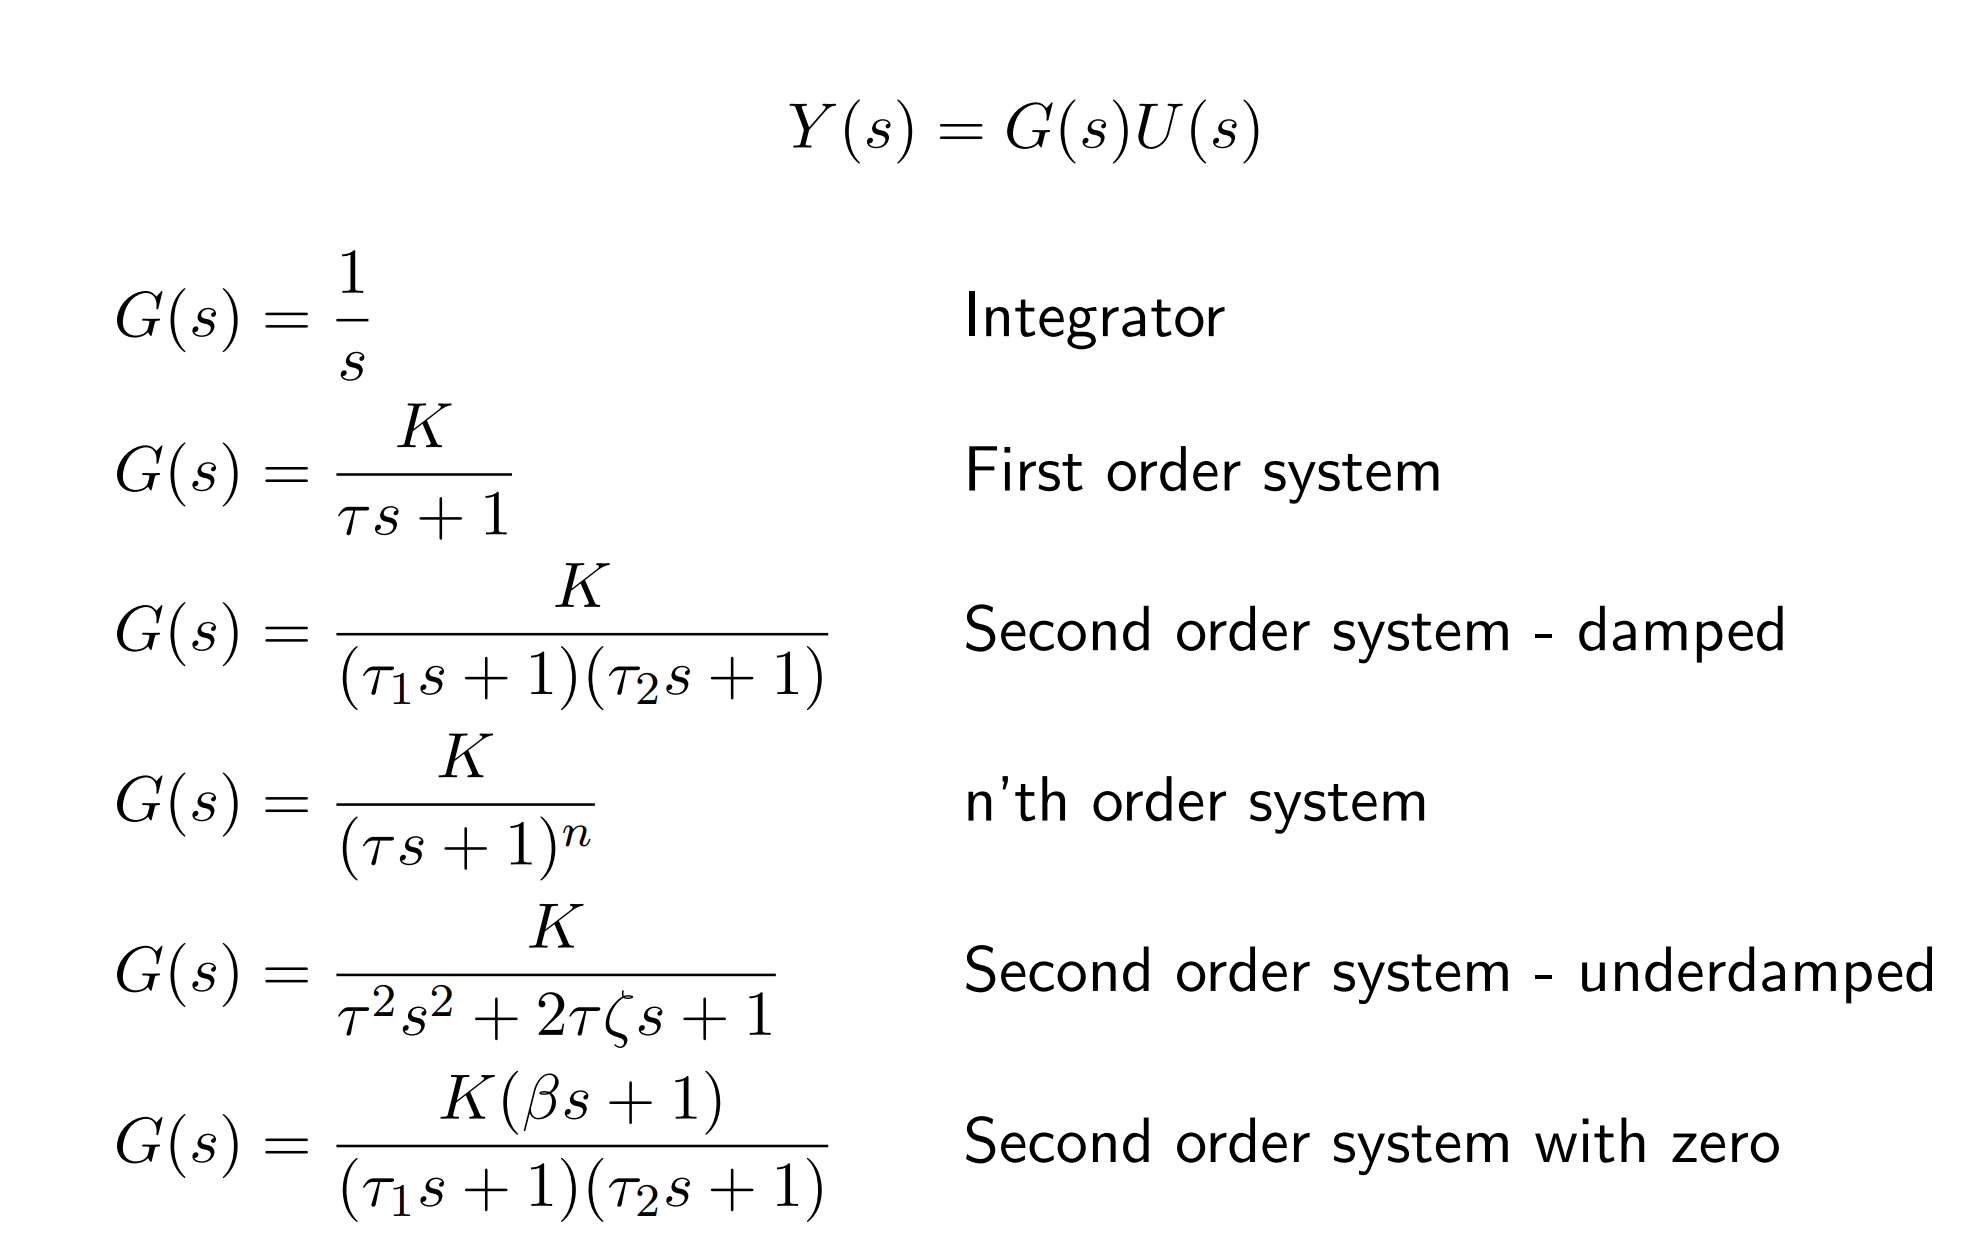

# 关于状态空间方程的离散化

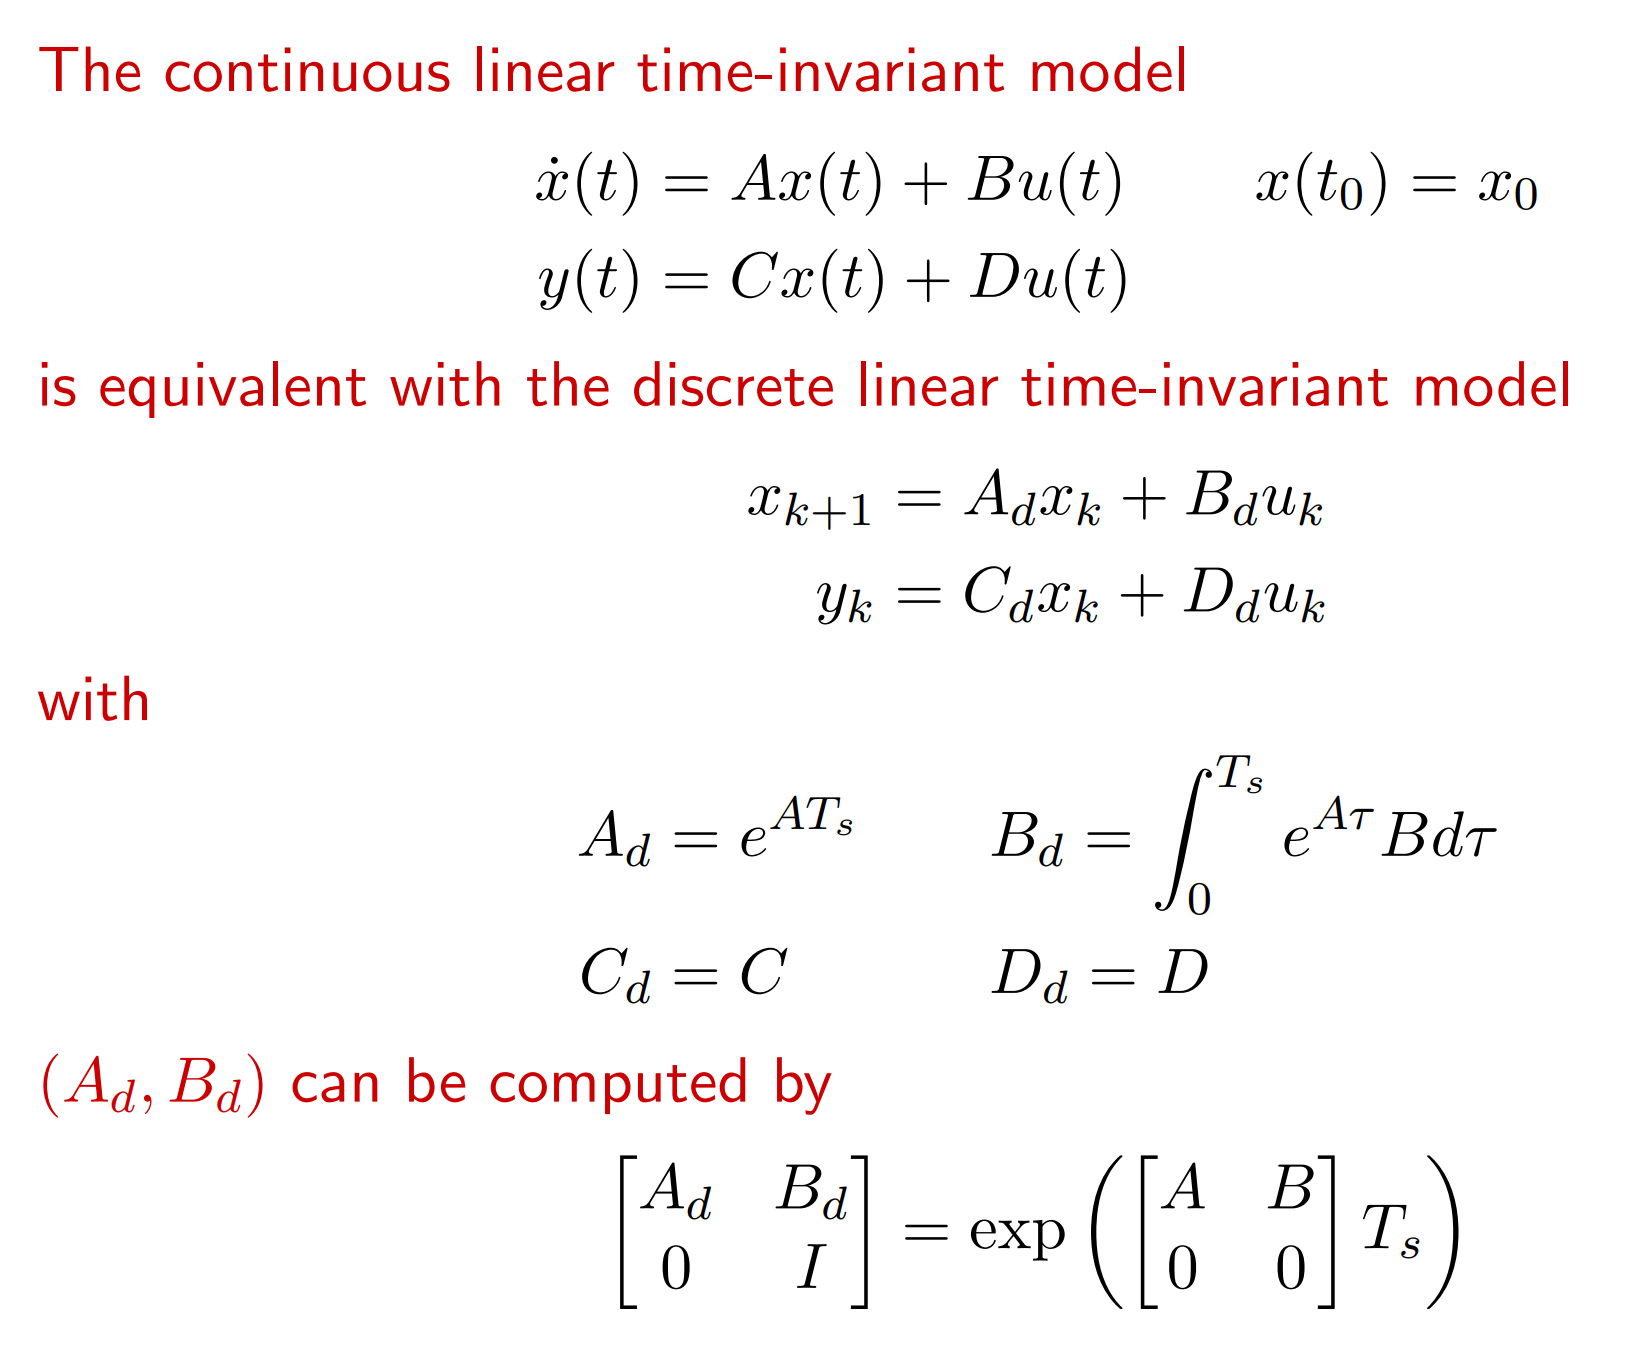

%连续状态方程离散化，上面那个式子关于零阶保持的公式运算
Ts = 10; 
[Ad,Bd]=c2dzoh(A,B,10)

Ad =     0.8839         0    0.1823         0
         0    0.8725         0    0.1957
         0         0    0.8058         0
         0         0         0    0.7901


Bd =     4.2335    0.5791
    0.5729    3.7392
         0    5.3965
    4.9002         0
